# Praktikum 4 - Shift 1 Selasa

`12 Oktober 2021`

`Nama : Carolina Sinaga`

`NIM  : 10119050`

## Nomor 1

Tuliskan kelebihan polinom interpolasi Newton dibanding interpolasi Lagrange !

#### **Jawaban :**

- **memudahkan perhitungan polinom dengan derajat lebih tinggi dikarenakan polinom newton menambahkan satu suku tunggal dengan polinom derajat lebih rendah**

- **tabel selisih terbagi yang didapat di polinom newton dapat digunakan berulang ulang untuk nilai x yang berbeda**

- **pada polinom newton, penambahan polinom dapat digunakan untuk menentukan apakah penambahan suku polinom akan memperbaiki nilai interpolasi atau tidak **

## Nomor 2

Bangunlah suatu fungsi `polinom_newton.m` yang menerima input array $X=[x_0, x_1, x_2, ..., x_n]$ dan $Y=[y_0, y_1, y_2, ..., y_n]$ dimana $f(x_i)=y_i$ untuk $1\leq i\leq n$  yang menghasilkan keluaran $p_n(x)$, polinom interpolasi Newton orde $n$ yang melalui semua titik $((x_0, f(x_0)), (x_1, f(x_1)), ..., (x_n, f(x_n))$.

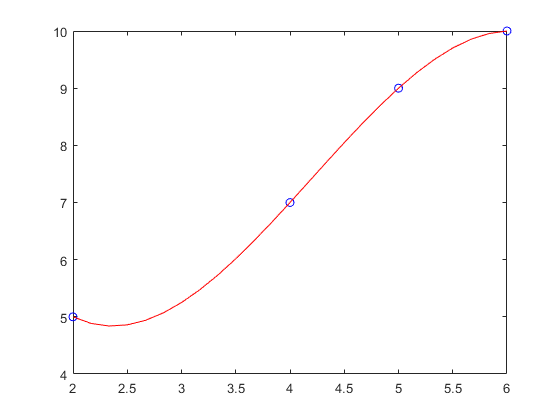

% Run section ini untuk memeriksa jawaban anda!
X = [2,6,5,4];
Y = [5,10,9,7];
X1 = linspace(2,6,25);
f = polinom_newton(X,Y);
plot(X,Y,'bo', X1, f(X1), 'r-')

## Nomor 3

Diketahui suatu objek dilempar ke atas dengan kecepatan awal $v_0$. Ternyata, ketinggian objek tersebut setiap saat dapat digambarkan oleh persamaan

### 
$$z(t)=z_0 + \frac{m}{c}\left(v_0+\frac{mg}{c} \right) (1-e^{-(c/m)t})-\frac{mg}{c}t$$


dengan 

- $z=$ ketinggian (m) diatas permukaan tanah

- $z_0=$ketinggian awal (m)

- $m=$massa objek (kg)

- $c=$koefisien *drag *(kg/s)

- $v_0=$kecepatan awal (m/s)

- $t=$ waktu (s)

Dilakukan eksperimen sebagai berikut: Objek seberat 900 gram dilempar ke atas dari ketinggian awal 75 meter diatas permukaan tanah, dengan kecepatan awal 10 m/s. Diketahui bahwa objek tersebut memiliki koefisien drag $c=$150 gram/s. Asumsikan $g=$9.81 m/s^2. Ketinggian benda diukur dari awal pelemparan ($t=0$) sampai $t=5$ sekon menggunakan sebuah sensor.

Ternyata, sensor tersebut mengalami kerusakan. Ketinggian benda hanya terukur ketika $t=0$, $t=2$, $t=4$, dan $t=5$ sekon. 

Diperoleh data sebagai berikut:

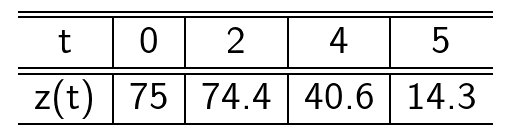

### 3A

Bangun polinom Interpolasi Newton orde 3 $p_3(t)$ menggunakan data yang diperoleh dari sensor !

% Lengkapi kode dibawah ini, lalu run section.
T = [0;2;4;5];
Z_T = [75;74.4;40.6;14.3];
p_3 = polinom_newton(T, Z_T);


%% Bagian I
% perhitungan untuk melengkapi 
% tabel beda terbagi Newton
n = length(T);
d = zeros(n,n);
d(:,1) = Z_T;
for j = 2:n
    for i = j:n
        d(i,j) = (d(i,j-1) - d(i-1,j-1)) / (T(i)-T(i-j+1));
    end
end
%% Bagian II
% perhitungan koefisien polinom interpolasi newton 
% untuk orde-k = 3  
k = 4;
c = d(k,k);
for kk = k-1 : -1: 1
    c = conv(c,poly(T(kk)));
    m = length(c);
    c(m) = c(m) + d(kk,kk);
end
%% Bagian III
% membentuk polinom interpolasi newton
syms x
p = 0;
l = length(c);
for i = 1:l
    p = c(i)*(x^(l-i)) +p;
end
p_n = matlabFunction(p)

p_n = function_handle with value:
    @(x)x.*(7.22e+2./7.5e+1)-x.^2.*(5.37e+2./1.0e+2)+x.^3.*(6.1e+1./3.0e+2)+7.5e+1


### 3B

Plot grafik polinom Interpolasi Newton orde 3 $p_3(t)$yang sudah diperoleh dari bagian $3A$ untuk $t\in [0,5]$, bersama dengan plot $z(t)$. Apa yang dapat kamu simpulkan dari grafik tersebut?

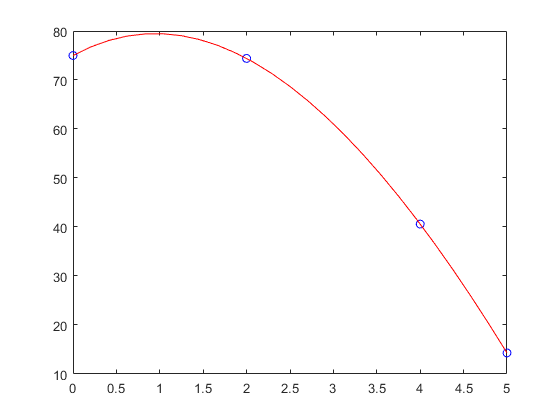

% Tuliskan jawaban dibawah garis.
% -------------------------------

% plot grafik polinom interpolasi newton orde 3
T1 = linspace(0,5,25);
plot(T,Z_T,'bo', T1, p_3(T1), 'r-')

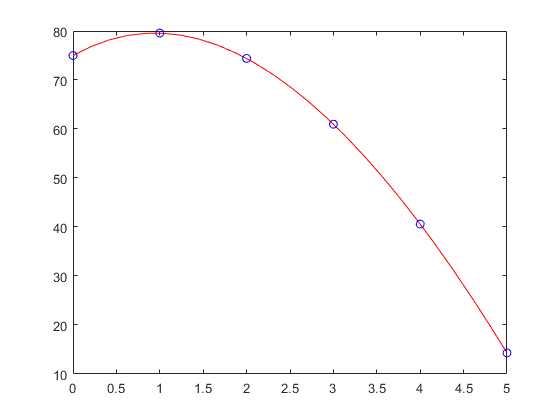

% plot grafik z(t)
% akan dicari nilai z(t) unutk
t = 1;
z = zeros(1,6);
z0 = 75;
z(1) = 75;

while t<7
    z(t+1) = z0 + (6*(68.86)*(1-exp(-t/6))) - 58.86*t;
    Z_T(t) = z(t);
    t = t+1;
end
T = [0,1,2,3,4,5];
z = @(t) 75 + (6*(68.86)*(1-exp(-t/6))) - 58.86*t;
t = linspace(0,5,25);
% PLOT
plot(t,z(t),'r-',T,Z_T,'bo')

## KESIMPULAN

% Dari grafik polinom newton yang diperoleh, 
% kita dapat mengetahui mengaproksimasi 
% berapa nilai z(t) t = 1 dan t= 3

% dan setelah dibandingkan dengan grafik z(t) aproksimasi 
% yang kita dapatkan sangat mendekati 

